# Final Dynamics

## Create State Variables

syms p_E_n p_E_e p_E_d phi theta psi u v w p q r

p_E = [p_E_n; p_E_e; p_E_d];
Theta = [phi; theta; psi];
V_b = [u; v; w];
omega_bE = [p; q; r];

## Problem 5 -- see problem 10 (lines 72-75)

## Problem 6

H = [1 0         -sin(theta);
     0 cos(phi)  sin(phi)*cos(theta);
     0 -sin(phi) cos(phi)*cos(theta)];

Theta_dot = H^(-1) * omega_bE

$$Theta\_dot = \begin{array}{l} \left(\begin{array}{c} p+\frac{r\,\cos\left(\varphi \right)\,\sin\left(\theta \right)}{\sigma_{1}}+\frac{q\,\sin\left(\varphi \right)\,\sin\left(\theta \right)}{\sigma_{1}}\\ \frac{q\,\cos\left(\varphi \right)}{{\cos\left(\varphi \right)}^{2}+{\sin\left(\varphi \right)}^{2}}-\frac{r\,\sin\left(\varphi \right)}{{\cos\left(\varphi \right)}^{2}+{\sin\left(\varphi \right)}^{2}}\\ \frac{r\,\cos\left(\varphi \right)}{\sigma_{1}}+\frac{q\,\sin\left(\varphi \right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta \right)\,{\cos\left(\varphi \right)}^{2}+\cos\left(\theta \right)\,{\sin\left(\varphi \right)}^{2} \end{array}$$

**Question 2: **gyroscope measurements are relative to the body frame, since sensors are only able to gather data in that frame. Pitch, yaw and roll rates refer to rates in the Earth NED frame. Therefore, gyroscopic measurements are the same as euler angle rates transformed from the Earth to body axes, and vice versa

** Question 3: on paper**

## Problem 7

**Part A: **done below, need to manually write out the work

syms m g 

% Part 2
R_Eb = [1 0         0;
        0 cos(phi)  sin(phi);
        0 -sin(phi) cos(phi)] * ...
        [cos(theta) 0 -sin(theta);
         0          1 0;
         sin(theta) 0 cos(theta)] * ...
        [cos(psi) sin(psi) 0;
        -sin(psi) cos(psi) 0;
        0         0        1];


F_gb = R_Eb * [0; 0; m*g]

$$F\_gb = \left(\begin{array}{c} -g\,m\,\sin\left(\theta \right)\\ g\,m\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\\ g\,m\,\cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$


% Part 3
m_sub = 82e3; % lbs
m_sub = m_sub * 0.453592; % kg

subs(F_gb, {phi, theta, m, g}, {45*pi/180, 60*pi/180, m_sub, 9.81})

$$ans = \left(\begin{array}{c} -3.1599e+05\\ 1.2900e+05\\ 1.2900e+05 \end{array}\right)$$


% part 4 

Despite yawing an additional 90 degrees, this does not change the force of gravity on the aircraft, because the gravitational force is not dependent on yaw (only dependent on roll and pitch).

## Problem 8

% Use rotation matrix from above 
V_E = R_Eb' * V_b

$$V\_E = \left(\begin{array}{c} w\,\left(\sin\left(\bar{\varphi }\right)\,\sin\left(\bar{\psi }\right)+\cos\left(\bar{\varphi }\right)\,\cos\left(\bar{\psi }\right)\,\sin\left(\bar{\theta }\right)\right)-v\,\left(\cos\left(\bar{\varphi }\right)\,\sin\left(\bar{\psi }\right)-\cos\left(\bar{\psi }\right)\,\sin\left(\bar{\varphi }\right)\,\sin\left(\bar{\theta }\right)\right)+u\,\cos\left(\bar{\psi }\right)\,\cos\left(\bar{\theta }\right)\\ v\,\left(\cos\left(\bar{\varphi }\right)\,\cos\left(\bar{\psi }\right)+\sin\left(\bar{\varphi }\right)\,\sin\left(\bar{\psi }\right)\,\sin\left(\bar{\theta }\right)\right)-w\,\left(\cos\left(\bar{\psi }\right)\,\sin\left(\bar{\varphi }\right)-\cos\left(\bar{\varphi }\right)\,\sin\left(\bar{\psi }\right)\,\sin\left(\bar{\theta }\right)\right)+u\,\cos\left(\bar{\theta }\right)\,\sin\left(\bar{\psi }\right)\\ w\,\cos\left(\bar{\varphi }\right)\,\cos\left(\bar{\theta }\right)-u\,\sin\left(\bar{\theta }\right)+v\,\cos\left(\bar{\theta }\right)\,\sin\left(\bar{\varphi }\right) \end{array}\right)$$


% find position by integrating w.r.t. time
syms p_E0 t t_f
p_E_int = p_E0 + int(V_E, t, [0 t_f])

$$p\_E\_int = \left(\begin{array}{c} p_{\mathrm{E0}}-t_{f}\,v\,\left(\cos\left(\bar{\varphi }\right)\,\sin\left(\bar{\psi }\right)-\cos\left(\bar{\psi }\right)\,\sin\left(\bar{\varphi }\right)\,\sin\left(\bar{\theta }\right)\right)+t_{f}\,w\,\left(\sin\left(\bar{\varphi }\right)\,\sin\left(\bar{\psi }\right)+\cos\left(\bar{\varphi }\right)\,\cos\left(\bar{\psi }\right)\,\sin\left(\bar{\theta }\right)\right)+t_{f}\,u\,\cos\left(\bar{\psi }\right)\,\cos\left(\bar{\theta }\right)\\ p_{\mathrm{E0}}+t_{f}\,v\,\left(\cos\left(\bar{\varphi }\right)\,\cos\left(\bar{\psi }\right)+\sin\left(\bar{\varphi }\right)\,\sin\left(\bar{\psi }\right)\,\sin\left(\bar{\theta }\right)\right)-t_{f}\,w\,\left(\cos\left(\bar{\psi }\right)\,\sin\left(\bar{\varphi }\right)-\cos\left(\bar{\varphi }\right)\,\sin\left(\bar{\psi }\right)\,\sin\left(\bar{\theta }\right)\right)+t_{f}\,u\,\cos\left(\bar{\theta }\right)\,\sin\left(\bar{\psi }\right)\\ p_{\mathrm{E0}}-t_{f}\,u\,\sin\left(\bar{\theta }\right)+t_{f}\,w\,\cos\left(\bar{\varphi }\right)\,\cos\left(\bar{\theta }\right)+t_{f}\,v\,\cos\left(\bar{\theta }\right)\,\sin\left(\bar{\varphi }\right) \end{array}\right)$$

## Problem 9

syms n1 n2 n3 n4 rho C_T D K_c


% F_Ab = - rho * C_T * D^4 * (n1^2 + n2^2 + n3^2 + n4^2) ...
%     * [K_c 0   0;
%        0   K_c 0;
%        0   0   0] ...
%     * [u; v; w];

% F_Ab = - Z ...
%     * [K_c 0   0;
%        0   K_c 0;
%        0   0   0] ...
%     * [u; v; w];
% 
% subs(F_Ab, K_c, 0.22)


## Problem 10

syms J % constants
syms X Y Z L M N % inputs
F_app = [X; Y; Z];
M_app = [L; M; N];

p_E_dot = V_E; % problem 8
% Theta_dot = Theta_dot; % problem 6 
V_b_dot = 1/m * (F_app + F_gb ... % problem 7
                 - cross(omega_bE, m*V_b)); % omega_bE from problem 6
omega_bE_dot = J^(-1) * (M_app - cross(omega_bE, J*omega_bE)); % J is moment of inertia for the drone (not incl. propellors)

f = [p_E_dot; Theta_dot; V_b_dot; omega_bE_dot]

$$f = \begin{array}{l} \left(\begin{array}{c} w\,\left(\sin\left(\bar{\varphi }\right)\,\sin\left(\bar{\psi }\right)+\cos\left(\bar{\varphi }\right)\,\cos\left(\bar{\psi }\right)\,\sin\left(\bar{\theta }\right)\right)-v\,\left(\cos\left(\bar{\varphi }\right)\,\sin\left(\bar{\psi }\right)-\cos\left(\bar{\psi }\right)\,\sin\left(\bar{\varphi }\right)\,\sin\left(\bar{\theta }\right)\right)+u\,\cos\left(\bar{\psi }\right)\,\cos\left(\bar{\theta }\right)\\ v\,\left(\cos\left(\bar{\varphi }\right)\,\cos\left(\bar{\psi }\right)+\sin\left(\bar{\varphi }\right)\,\sin\left(\bar{\psi }\right)\,\sin\left(\bar{\theta }\right)\right)-w\,\left(\cos\left(\bar{\psi }\right)\,\sin\left(\bar{\varphi }\right)-\cos\left(\bar{\varphi }\right)\,\sin\left(\bar{\psi }\right)\,\sin\left(\bar{\theta }\right)\right)+u\,\cos\left(\bar{\theta }\right)\,\sin\left(\bar{\psi }\right)\\ w\,\cos\left(\bar{\varphi }\right)\,\cos\left(\bar{\theta }\right)-u\,\sin\left(\bar{\theta }\right)+v\,\cos\left(\bar{\theta }\right)\,\sin\left(\bar{\varphi }\right)\\ p+\frac{r\,\cos\left(\varphi \right)\,\sin\left(\theta \right)}{\sigma_{1}}+\frac{q\,\sin\left(\varphi \right)\,\sin\left(\theta \right)}{\sigma_{1}}\\ \frac{q\,\cos\left(\varphi \right)}{\sigma_{2}}-\frac{r\,\sin\left(\varphi \right)}{\sigma_{2}}\\ \frac{r\,\cos\left(\varphi \right)}{\sigma_{1}}+\frac{q\,\sin\left(\varphi \right)}{\sigma_{1}}\\ \frac{X-g\,m\,\sin\left(\theta \right)-m\,q\,w+m\,r\,v}{m}\\ \frac{Y+m\,p\,w-m\,r\,u+g\,m\,\cos\left(\theta \right)\,\sin\left(\varphi \right)}{m}\\ \frac{Z-m\,p\,v+m\,q\,u+g\,m\,\cos\left(\varphi \right)\,\cos\left(\theta \right)}{m}\\ \frac{L}{J}\\ \frac{M}{J}\\ \frac{N}{J} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta \right)\,{\cos\left(\varphi \right)}^{2}+\cos\left(\theta \right)\,{\sin\left(\varphi \right)}^{2}\\ \sigma_{2}={\cos\left(\varphi \right)}^{2}+{\sin\left(\varphi \right)}^{2} \end{array}$$


x = [p_E; Theta; V_b; omega_bE]

$$x = \left(\begin{array}{c} p_{E,n}\\ p_{E,e}\\ p_{E,d}\\ \varphi \\ \theta \\ \psi \\ u\\ v\\ w\\ p\\ q\\ r \end{array}\right)$$

u = [F_app; M_app]

$$u = \left(\begin{array}{c} X\\ Y\\ Z\\ L\\ M\\ N \end{array}\right)$$


x_0 = zeros(12, 1);
u_0 = [0; 0; -m*g; 0; 0; 0];

## Problem 11

f_x = jacobian(f, x);
A = subs(f_x, x, x_0)

$$A = \left(\begin{array}{cccccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & -g & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & g & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$


f_u = jacobian(f, u);
B = subs(f_u, u, u_0)

$$B = \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ \frac{1}{m} & 0 & 0 & 0 & 0 & 0\\ 0 & \frac{1}{m} & 0 & 0 & 0 & 0\\ 0 & 0 & \frac{1}{m} & 0 & 0 & 0\\ 0 & 0 & 0 & \frac{1}{J} & 0 & 0\\ 0 & 0 & 0 & 0 & \frac{1}{J} & 0\\ 0 & 0 & 0 & 0 & 0 & \frac{1}{J} \end{array}\right)$$

## Simulink Workspace Stuff

% constants
Ixx = 2.3951e-5;
Iyy = 2.3951e-5;
Izz = 3.2347e-5; % all kg/m^2
g = 9.81;
m = 0.03175; % kg, measured from lab
% m = 0.027;   % kg, from datasheet
% TODO might want to check mit link to see a different measurement of mass
s = tf('s');
int = 1/s;

% transfer functions
% (1)
L2p = 1/Ixx * int;
p2phi = int;
phi2v = g * int;
v2p_y = int;

% (2)
M2q = 1/Iyy * int;
q2theta = int;
theta2u = -g * int;
u2p_x = int;

% (3) 
N2r = 1/Izz * int;
r2psi = int;

% (4)
Z2w = 1/m * int;
w2p_z = int;

% controllers
% (1)
p_p = Ixx/Izz*0.05;
p_phi = 25;
p_v = 2.5/g;
p_p_y = 1.5;

% (2) 
p_q = Ixx/Izz*0.05;
p_theta = 25;
p_u = 2.5/g; % NOTE this is a negative gain in Simulink!!!
p_p_x = 1.5;

% (3)
p_r = 0.05; % NOTE these need to be small because the dynamics have a huge gain due to I
p_psi = 25;

% (4)
p_w = 3;
p_p_z = 1;

% bandwidth
% (1)
disp('(1) ------------------')

(1) ------------------


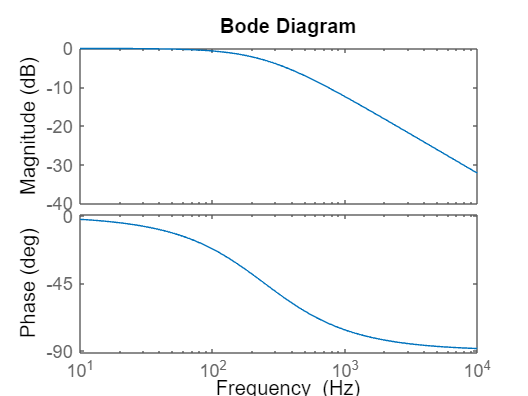

plot_bandwidth(L2p*p_p)

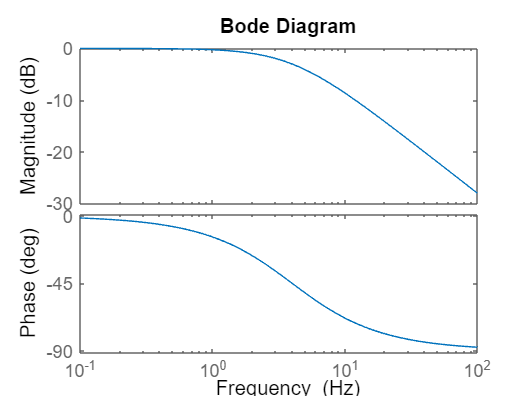

plot_bandwidth(p2phi*p_phi)

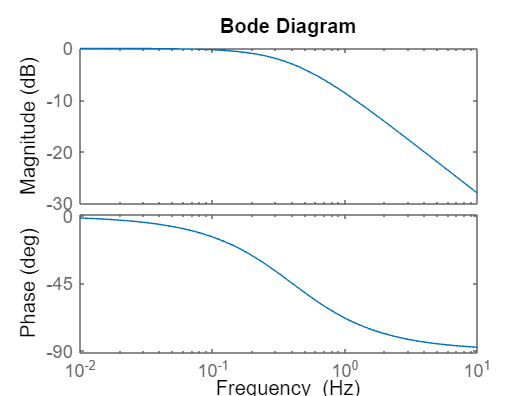

plot_bandwidth(phi2v*p_v)

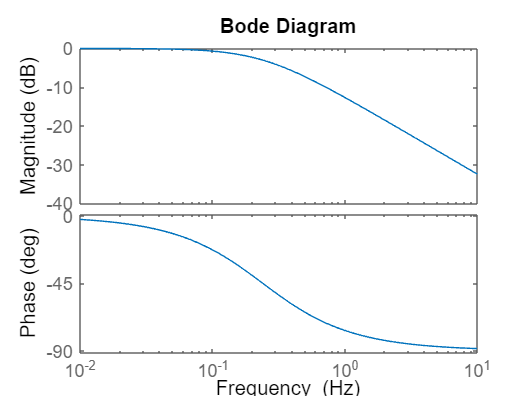

plot_bandwidth(v2p_y*p_p_y)


% (2)
disp('(2) ------------------')

(2) ------------------


plot_bandwidth(M2q*p_q)

plot_bandwidth(q2theta*p_theta)

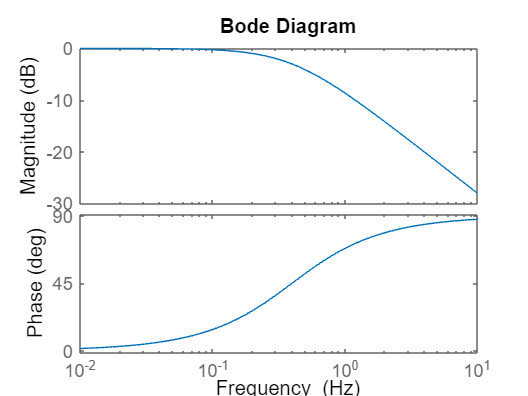

plot_bandwidth(theta2u*p_u)

plot_bandwidth(u2p_x*p_p_x)


% (3)
disp('(3) ------------------')

(3) ------------------


plot_bandwidth(N2r*p_r)

plot_bandwidth(r2psi*p_psi)


% (4) 
disp('(4) ------------------')

(4) ------------------


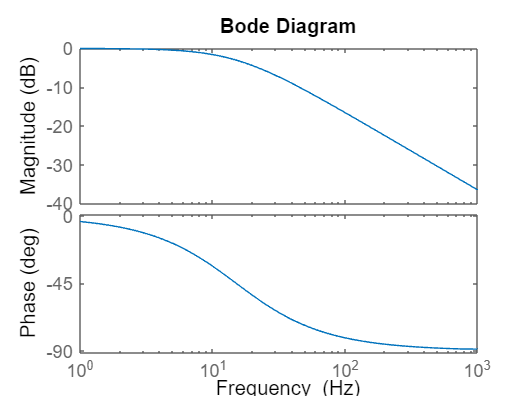

plot_bandwidth(Z2w*p_w)

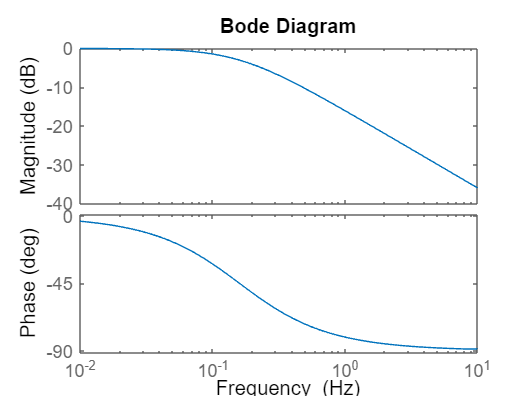

plot_bandwidth(w2p_z*p_p_z)